clear;
clc;
addpath("../interpolation/")

% m1 = 2.0;  % (kg) Cart mass
% m2 = 0.5;  % (kg) pole mass
% l = 0.5;   % (m) pendulum (pole) length
% 
% dist = 0.8;  %How far must the cart translate during its swing-up
% maxForce = 100;  %Maximum actuator forces
% duration = 2;

m1 = 5;  % (kg) Cart mass
m2 = 1;  % (kg) pole mass
l = 2;   % (m) pendulum (pole) length

dist = 0.8;  %How far must the cart translate during its swing-up
maxForce = 200;  %Maximum actuator forces
duration = 2;

## Objective

times = 0:0.1:duration;
len = size(times, 2);
force_square_obj = @(x) simpson(times,x(8*len-3:10*len-5).^2);

## Formulation

LB = [ones(len, 1)*(-2*dist); ones(len-1, 1)*(-2*dist); ones(len, 1)*(-2*pi); ones(len-1, 1)*(-2*pi); ...
    ones(len, 1)*(-inf); ones(len-1, 1)*(-inf); ones(len, 1)*(-inf); ones(len-1, 1)*(-inf); ...
    ones(len, 1)*(-maxForce); ones(len-1, 1)*(-maxForce)]; %Lower Bounds

UB = [ones(len, 1)*(2*dist); ones(len-1, 1)*(2*dist); ones(len, 1)*(2*pi); ones(len-1, 1)*(2*pi); ...
    ones(len, 1)*(inf); ones(len-1, 1)*(inf); ones(len, 1)*(inf); ones(len-1, 1)*(inf); ...
    ones(len, 1)*(maxForce); ones(len-1, 1)*(maxForce)]; %Upper Bounds

target = [dist, pi, 0, 0];

X0 = [linspace(0, target(1), 2*len-1)'; linspace(0, target(2), 2*len-1)'; ...
    zeros(len, 1); zeros(len-1, 1); zeros(len, 1); zeros(len-1, 1); ...
    zeros(len, 1); zeros(len-1, 1)]; %Initial Condition

A = []; %No linear inequality constraints
B = [];

Aeq = []; %No linear equality constraints
Beq = [];

options = optimoptions('fmincon',...
                       'Algorithm', 'sqp',...
                       'Display', 'iter-detailed',...
                       'MaxFunctionEvaluations', 1000000,...
                       'MaxIterations', 2000,...
                       'FunctionTolerance', 1e-10);

## Solve NLP

[X, Cost] = fmincon(@(x) force_square_obj(x), X0, A, B, Aeq, Beq, LB, UB,...
            @(x) simpson_constraints(x, m1, m2, l, times, target), options);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         206    0.000000e+00     4.892e-01     1.000e+00     0.000e+00     9.934e-10  
    1         412    2.472263e-01     1.491e+00     1.000e+00     1.337e+01     2.242e+02  
    2         618    8.027260e+03     9.843e-01     1.000e+00     3.660e+02     8.165e+03  
    3         825    1.352115e+04     3.225e-01     7.000e-01     1.164e+02     6.682e+03  
    4        1031    2.201504e+04     2.548e-01     1.000e+00     2.386e+02     1.414e+04  
    5        1237    2.849432e+04     5.726e-02     1.000e+00     2.607e+02     4.103e+04  
    6        1443    2.749200e+04     2.088e-02     1.000e+00     1.110e+02     5.702e+03  
    7        1649    2.496992e+04     4.429e-02     1.000e+00     1.351e+02     7.161e+03  
    8        1855    2.294818e+04     3.305e-02     1.000e+00     1.256e+02     7.

## Plot

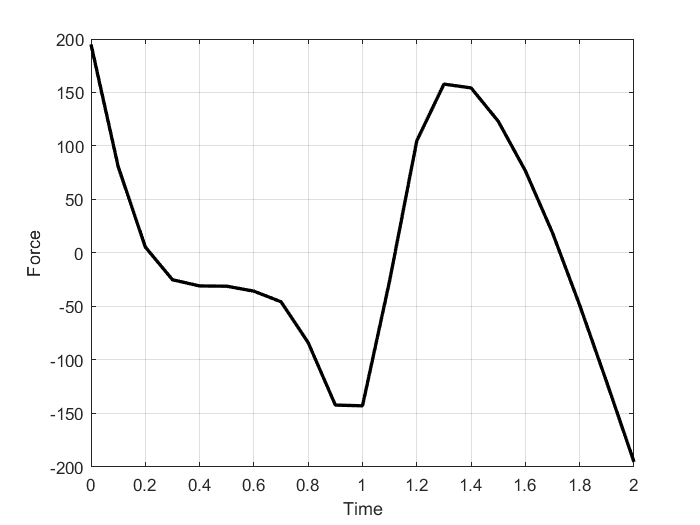

q1 = X(1:2:2*len-1);
q2 = X(2*len:2:4*len-2);
u = X(8*len-3:2:10*len-5);

figure(1);
plot(times, u,'k', 'LineWidth', 2);
axis auto;
grid on;
xlabel('Time');
ylabel('Force');

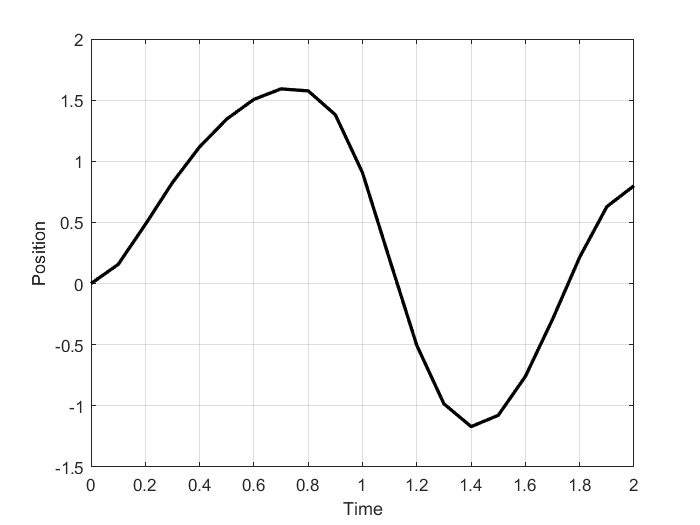


figure(2);
plot(times, q1,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Position');

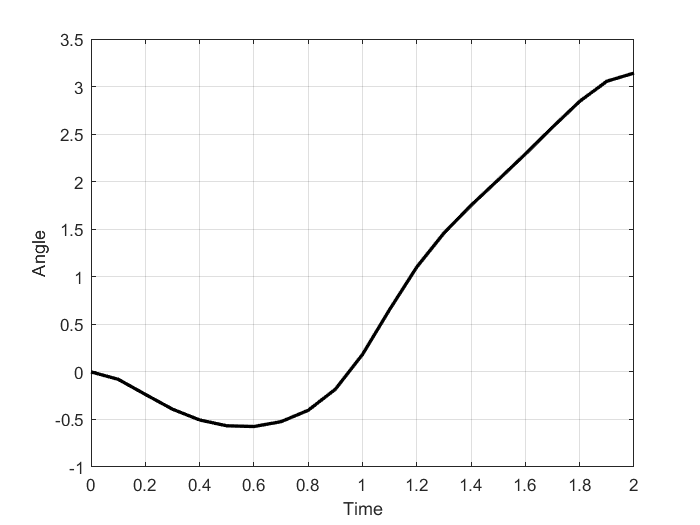


figure(3);
plot(times, q2,'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Angle');

## Interpolation

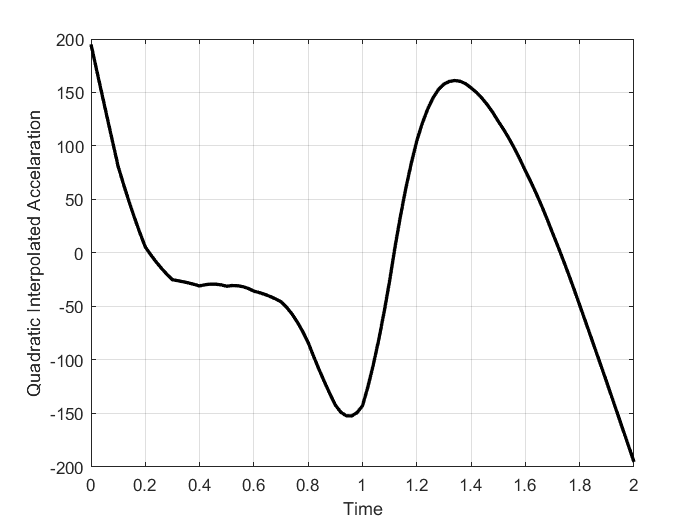

q1 = X(1:2*len-1);
q2 = X(2*len:4*len-2);
q1_d = X(4*len-1:6*len-3);
q2_d = X(6*len-2:8*len-4);
u = X(8*len-3:10*len-5);

tm = 0:0.02:duration;

u_i = [];
for i = 1:size(tm, 2)
    u_i = [u_i, midpoint_quadratic_interpolate(times, u, tm(i))];
end
figure(4);
plot(tm, u_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Quadratic Interpolated Accelaration');

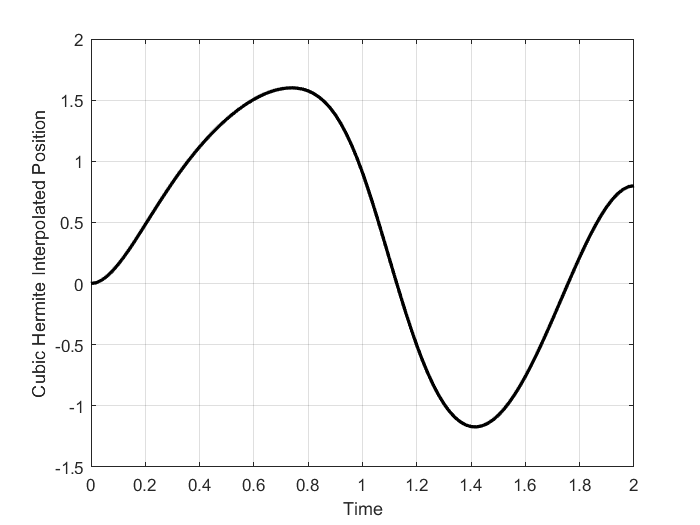


q1_i = [];
for i = 1:size(tm, 2)
    q1_i = [q1_i, cubic_hermite_interpolate(times, q1, q1_d, tm(i))];
end
figure(5);
plot(tm, q1_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Cubic Hermite Interpolated Position');

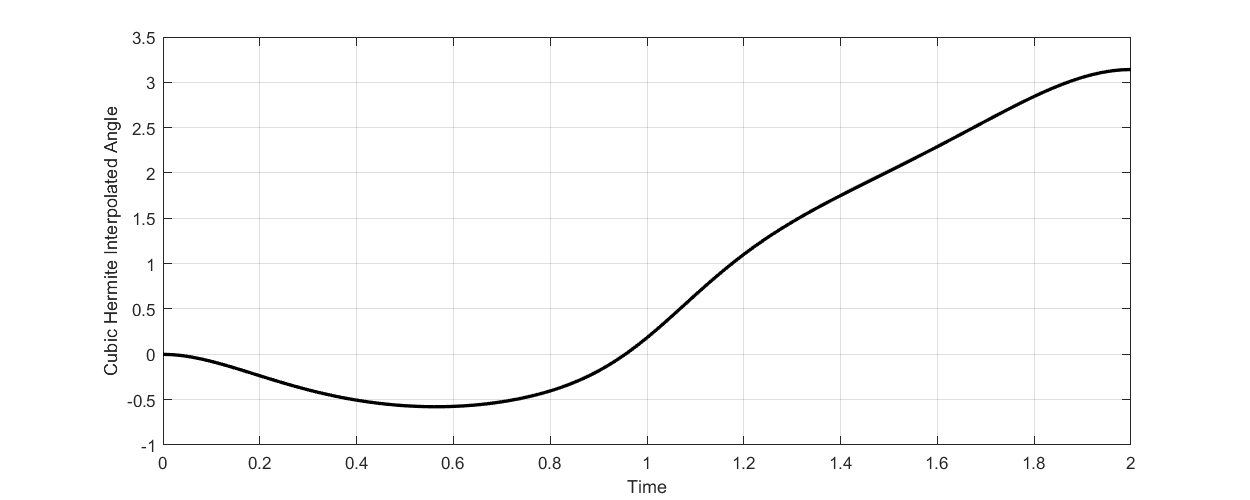


q2_i = [];
for i = 1:size(tm, 2)
    q2_i = [q2_i, cubic_hermite_interpolate(times, q2, q2_d, tm(i))];
end
figure(6);
plot(tm, q2_i, 'k', 'LineWidth', 2);
grid on;
xlabel('Time');
ylabel('Cubic Hermite Interpolated Angle');

## Simulation

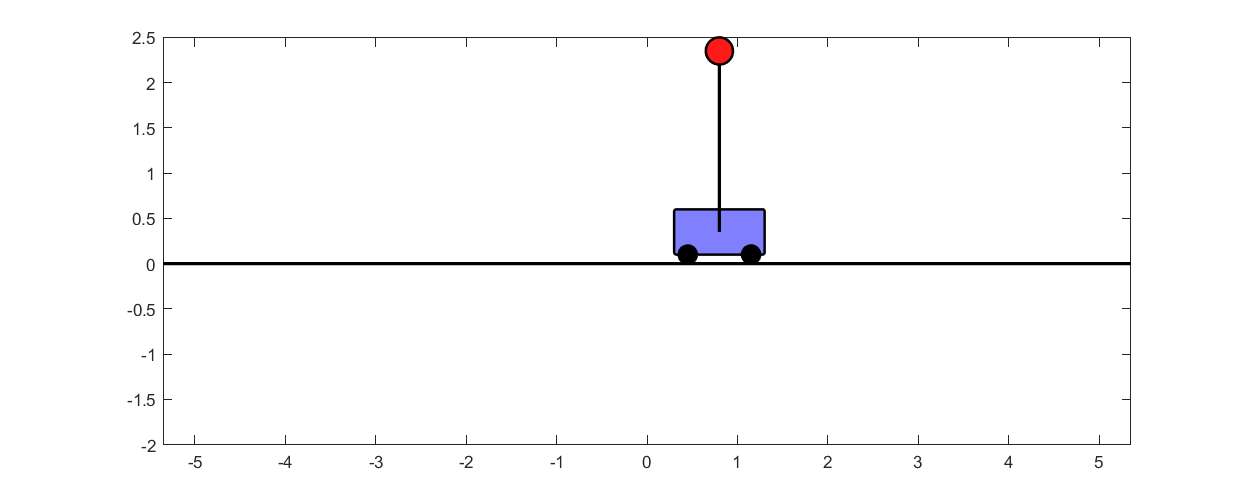

sim_data = [transpose(q1_i), transpose(q2_i)];
for k=1:1:size(tm, 2)
    drawpend(sim_data(k,:),m2,m1,l);
end